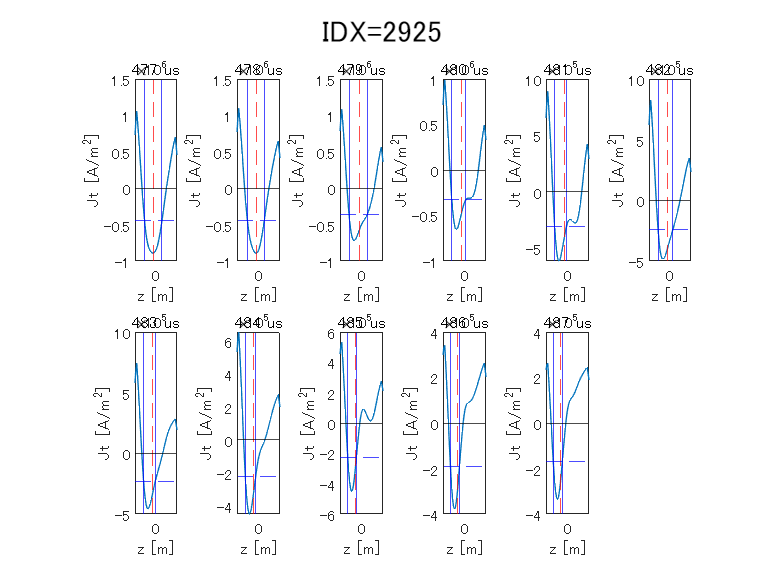

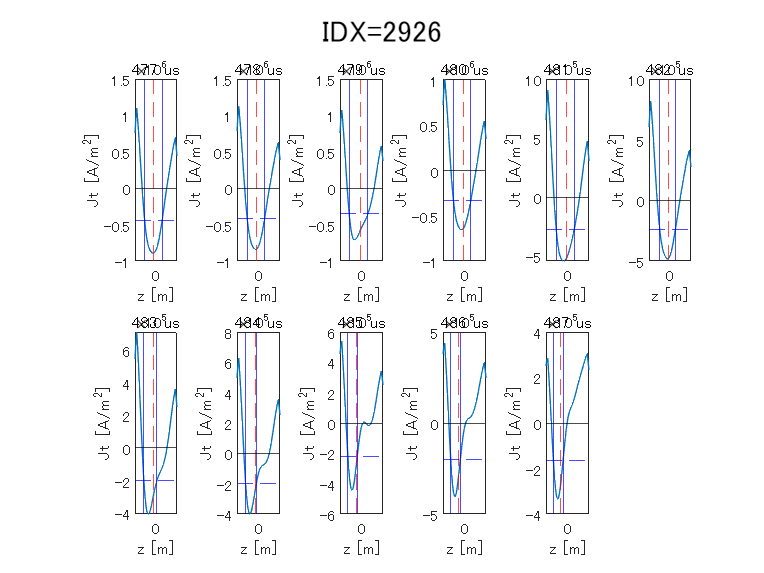

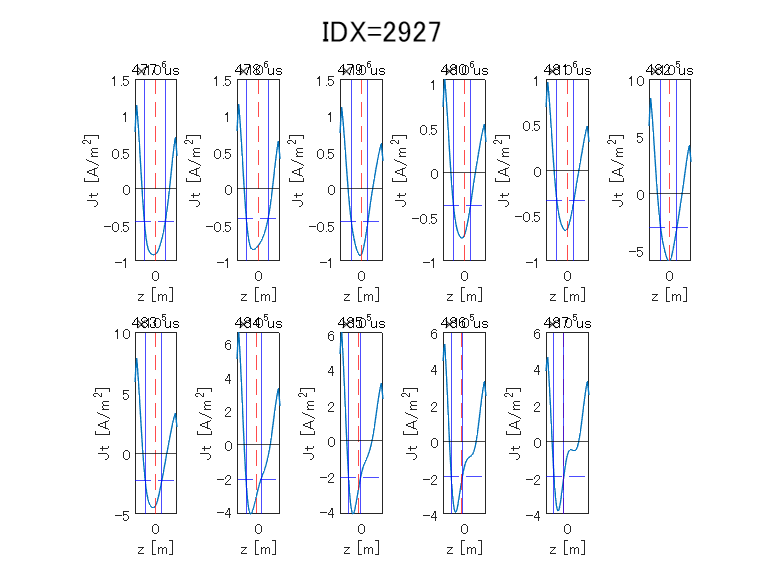

clearvars 
%電流シートの傾きを求める（test）
%磁気面上での表示、時系列での傾き
%%ファイルへのパスを作る
%それぞれのPCから共有フォルダまでのパスはそれぞれ異なるので各自で設定
pathname.ts3u=getenv('ts3u_path');%old-koalaのts-3uまでのパス
pathname.fourier=getenv('fourier_path');%md0までのpath
pathname.NIFS=getenv('NIFS_path');%resultsまでのpath
pathname.save='C:\Users\kuru1\OneDrive - g.ecc.u-tokyo.ac.jp\過去データ解析\220809';

DOCID='1wG5fBaiQ7-jOzOI-2pkPAeV6SDiHc_LrOdcbWlvhHBw';
T=getTS6log(DOCID);% ログのテーブルを取得

% start=460;
% frame=50;
% elapsedtime=1:frame;
% trange=[1:frame]+start;

IDXlist=[2911:2913 2925 2926 2927 2931 2933 2947:2950 2942 2943 2946];
% tstartlist=[472 472 472 477 477 477 482 482];
% tendlist=[482 482 482 487 487 487 500 500];
tstart=472;
tend=482;

wide=zeros(tend-tstart+1,3); %電流シートの半値幅
% xr=zeros(numel(IDXlist),numel(tcal));
% Vzl=zeros(numel(IDXlist),numel(tcal));
% Vzr=zeros(numel(IDXlist),numel(tcal));

for i=1:3%numel(IDXlist)
    IDX=IDXlist(i);
%     tstart=tstartlist(i);
%     tend=tendlist(i);
    wide(:,i)=cal_diff(T, IDX, pathname, tstart, tend);
    %catで書き直した方がよい
%     [wide(i),xr(i),Vzl(i),Vzr(i)]=jtsheetcalc(T, IDX, pathname, tstart, tend);
%     [wide(i,:),xr(i,:),Vzl(i,:),Vzr(i,:)]=cal_vz(T, IDX, pathname, tstart, tend);
end


% figure
% for i=1:3
% plot(tstart:tend,wide(:,i))
% hold on
% end
% hold off
% xlabel('Time [us]')
% ylabel('delta [m]')


function [date, shot, TF_shot, offset_TF, i_EF, start, v_TF, d_tacq, d_tacqTF, n] = getinput(T,IDX)
date=T.date(IDX);
shot=T.shot(IDX);
TF_shot=T.TFoffset(IDX);
offset_TF=isfinite(TF_shot);

if isnan(T.EF_A_(IDX))%%NaNでないことを確認（ログが空白だとNaNになる）
    i_EF=150;
else  %NaNなら150をとりあえず代入、記入されているときはその値を使う
    i_EF=T.EF_A_(IDX);
end

start=T.Period_StartTime_(IDX);
v_TF=T.TF_kV_(IDX); %TF[kV]

d_tacq=T.d_tacq(IDX);
d_tacqTF=T.TFdtacq(IDX);

n=50; %rz方向のメッシュ数
end

function wide=cal_diff(T, IDX, pathname, tstart, tend)
trange = tstart:tend+1;
tsize = tend-tstart+1;

row = 2;
column =ceil(tsize/row);

[date, ~, ~, ~, i_EF, ~, ~, d_tacq, d_tacqTF, n] = getinput(T,IDX);%Tのテーブルから入力のリストを出力
[grid2D, data2D] = pcbdata(date, d_tacq, d_tacqTF, trange, [], n,i_EF);

if isstruct(grid2D)==0 %もしdtacqデータがない場合次のloopへ(データがない場合NaNを返しているため)
    return
end

%%%midplaneとかO点、X点を探す
[psimid,mid]=min(data2D.psi,[],2);
[opoint,~]=islocalmin(psimid,1);
[xpoint,~]=islocalmax(psimid,1);
% [xp_psi,maxxp]=max(squeeze(psimid),[],1);
r_index=1:n;

dr=grid2D.rq(2,1)-grid2D.rq(1,1);
dz=grid2D.zq(1,2)-grid2D.zq(1,1);
r_value=grid2D.rq(:,1);

%X点での勾配
Q_n=zeros(n,1);
Q_s=Q_n;
pi=zeros(2,tsize);
vi=zeros(2,tsize);
p=zeros(2,tsize);
v=zeros(2,tsize);
wide=zeros(tsize,1);
% figure('Position',[0,0,600,400])
figure%('Position', [0 0 1500 1500],'visible','on');
for i=1:tsize
%     r_xind=ceil(n/2);
%     z_xind=ceil(n/2);

% search Xpoint posision (index)
    if sum(xpoint(:,:,i))>0   
        r_xind=r_index(xpoint(:,:,i));
        z_xind=mid(xpoint(:,:,i),:,i);
        if numel(r_xind)>1
            [~,I]=max(psimid(r_xind));
            r_xind=r_xind(I);
            z_xind=z_xind(I);
        end
        
        r_s=max(2,r_xind-5);
        r_n=min(n,r_xind+5);

% Xpontの上下5マス間でのmid-planeの線形近似
        p(:,i)=polyfit(grid2D.rq(r_s:r_n,1),grid2D.zq(1,squeeze(mid(r_s:r_n,:,i))),1);
        diff=polyval(p(:,i),grid2D.rq(r_s:r_n,1));

        v(:,i)=[-p(1,i) grid2D.rq(r_xind,1)+p(1,i).*grid2D.zq(1,z_xind)];%mid-planeに垂直な直線の係数
        vertical=polyval(v(:,i),grid2D.zq(1,1:n));

%         if i==1
%             midplane=diff;
%             sheetline=vertical;
%         else
%             midplane=cat(2,midplane,diff);
%             sheetline=cat(2,sheetline,vertical);
%         end
        
        ep=[p(1,i) 1]./(p(1,i)^2+1); %シートに平行な単位ベクトル
        ev=[1 v(1,i)]./(v(1,i)^2+1); %シートに垂直な単位ベクトル

        for j=1:n
            if r_value(n)>vertical(j)%傾きが大きく、シート幅右端がrmaxの端から出た場合を省く
               Q_n(j)=min(r_value(r_value>vertical(j)));
               Q_s(j)=max(r_value(r_value<=vertical(j)));
            else
                Q_n(j)=NaN;
                Q_s(j)=NaN;
            end 
        end
        
        Q_nind=round((Q_n-grid2D.rq(1,1))./dr)+1;
        Q_sind=round((Q_s-grid2D.rq(1,1))./dr)+1;

        Q_nind(isnan(Q_nind)) = [];
        Q_sind(isnan(Q_sind)) = [];
        nq=numel(Q_nind);%表示されるverticalの要素

        Bp_n=diag(data2D.Bz(Q_nind,:,i)).*ep(1)+diag(data2D.Br(Q_nind,:,i)).*ep(2);
        Bv_n=diag(data2D.Bz(Q_nind,:,i)).*ev(1)+diag(data2D.Br(Q_nind,:,i)).*ev(2);
        Jt_n=diag(data2D.Jt(Q_nind,:,i));
        Bp_s=diag(data2D.Bz(Q_sind,:,i)).*ep(1)+diag(data2D.Br(Q_sind,:,i)).*ep(2);
        Bv_s=diag(data2D.Bz(Q_sind,:,i)).*ev(1)+diag(data2D.Br(Q_sind,:,i)).*ev(2);
        Jt_s=diag(data2D.Jt(Q_sind,:,i));

%         % 交点の上下の平均値で考える場合
%         Bp=(Bp_n+Bp_s)./2;
%         Bv=(Bv_n+Bv_s)./2;
%         Jt=(Jt_n+Jt_s)./2;

        % 内分で考える場合
        di=[vertical'-Q_s Q_n-vertical'];%internally divide
        di=di(1:nq,:);
        
        Jt=dot(di, [Jt_n Jt_s],2)./dr;
        Bp=dot(di, [Bp_n Bp_s],2)./dr;
        Bv=dot(di, [Bv_n Bv_s],2)./dr;

        [~,min_ind]=min(Jt);

        % polyxpoly　直線近似での交点
        [zi,yi,ii]=polyxpoly(grid2D.zq(1,1:nq),Jt,grid2D.zq(1,1:nq),ones(nq,1).*min(Jt).*0.5);
        if numel(ii)>2
            P=ii-min_ind;
            [~,I]=sort(P,'ascend'); %小さい順に並び替え
%             ii=[ii(I(1)) ii(I(2))];
            zi=[zi(I(1)) zi(I(2))];
%             yi=[yi(I(1)) yi(I(2))];
        end
        ri=polyval(v(:,i),[zi(1) zi(2)]);

%         if i==1
%             zwide=zi';
%             rwide=ri';
%         else
%             zwide=cat(2,zwide,zi');
%             rwide=cat(2,rwide,ri');
%         end

        wide(i)=norm([zi(2)-zi(1) ri(2)-ri(1)]);

%         % 一番近い点を求める場合
%         Jt_left=Jt(1:min_ind);%Jt(1:z_xind);
%         Jt_right=Jt(min_ind+1:nq);%Jt(z_xind+1:n);
% 
%         [~,left_ind]=max(Jt_left(Jt_left<=min(Jt)*0.5));
%         [~,right_ind]=max(Jt_right(Jt_right<=min(Jt)*0.5));
% 
%         kari_l=find(Jt_left<=min(Jt)*0.5);
%         kari_r=find(Jt_right<=min(Jt)*0.5);
% 
%         left_ind=max(kari_l(1)+left_ind-1,1);
%         right_ind=min(kari_r(1)+min_ind+right_ind-1,nq);%min(kari_r(1)+z_xind+right_ind-1,n);
%         wide(i)=(grid2D.zq(1,right_ind)-grid2D.zq(1,left_ind))^2+((grid2D.rq(Q_sind(right_ind),1)+grid2D.rq(Q_nind(right_ind),1)-grid2D.rq(Q_sind(left_ind),1)-grid2D.rq(Q_nind(left_ind),1))*0.5)^2;
%         wide(i)=sqrt(wide(i));
      
        subplot(row,column,i)
        plot(grid2D.zq(1,1:nq),Jt)
        xline(grid2D.zq(1,z_xind),'r--')
        yline(min(Jt)*0.5,'b--')
        xline(zi(1),'b-')%xline(grid2D.zq(1,left_ind),'b-')
        xline(zi(2),'b-')%xline(grid2D.zq(1,right_ind),'b-')
        yline(0,'k-')
        xlabel('z [m]')
        ylabel('Jt [A/m^{2}]')
        xlim([grid2D.zq(1,1) grid2D.zq(1,n)])
%         ylim([-1.5e+6 1.5e+6])%(a)
%         ylim([-1e+6 1.5e+6])%(b)
        title(string(tstart+i-1)+' us')

%         subplot(row,column,i)
%         contourf(grid2D.zq(1,:),grid2D.rq(:,1),-1.*data2D.Jt(:,:,i),8,'w-','LineWidth',0.2);
%         colormap(jet)
%         caxis([-2.5*1e+6,1.6*1e+6])
%         axis image
%         axis tight manual
%         hold on
%         contour(grid2D.zq(1,:),grid2D.rq(:,1),squeeze(data2D.psi(:,:,i)),20,'black','LineWidth',0.3)
%         colorbar('Location','eastoutside')
%         plot(diff,grid2D.rq(r_s:r_n,1),'r-','LineWidth',2)
%         plot(grid2D.zq(1,:),vertical,'r-','LineWidth',2)
%         plot(grid2D.zq(1,squeeze(mid(xpoint(:,:,i),:,i))),grid2D.rq(xpoint(:,:,i),1),"bx",'MarkerSize',8)%Xpoint
%         plot(grid2D.zq(1,left_ind),(grid2D.rq(Q_sind(left_ind),1)+grid2D.rq(Q_nind(left_ind),1))*0.5,'b*','MarkerSize',8)
%          plot(grid2D.zq(1,right_ind),(grid2D.rq(Q_sind(right_ind),1)+grid2D.rq(Q_nind(right_ind),1))*0.5,'b*','MarkerSize',8)
% %         plot(grid2D.zq(1,squeeze(mid(:,:,i))),grid2D.rq(:,1),'b-','LineWidth',1)
%         hold off
%         alpha(0.3)
% %         ylim([0.1 grid2D.rq(end,1)])
% %         xlim([-0.04 0.04])
%         xlabel('z [m]')
%         ylabel('r [m]')
%         title(string(tstart+i-1)+' us')

        if z_xind==1 || z_xind==n
            pi(:,i)=NaN;
        end
    else
        pi(:,i)=NaN;
    end

end
sgtitle(strcat('IDX=',num2str(IDX)))
% saveas(gcf,strcat(pathname.save,'\IDX',num2str(IDX),'jt.png'))
% close

% %磁気面上にプロットして確認
% figure
% for i=1:tsize
%         subplot(row,column,i)
%         contourf(grid2D.zq(1,:),grid2D.rq(:,1),-1.*data2D.Jt(:,:,i),8,'w-','LineWidth',0.2);
%         colormap(jet)
%         caxis([-2.5*1e+6,1.6*1e+6])
%         axis image
%         axis tight manual
%         hold on
%         contour(grid2D.zq(1,:),grid2D.rq(:,1),squeeze(data2D.psi(:,:,i)),20,'black','LineWidth',0.3)
% %         colorbar('Location','eastoutside')
%         plot(midplane,grid2D.rq(r_s:r_n,1),'r-','LineWidth',2)
%         plot(grid2D.zq(1,n),sheetline,'r-','LineWidth',2)
% %         plot(grid2D.zq(1,squeeze(mid(xpoint(:,:,i),:,i))),grid2D.rq(xpoint(:,:,i),1),"bx",'MarkerSize',8)%Xpoint-all
%         plot(grid2D.zq(1,z_xind),grid2D.rq(r_xind,1),"bx",'MarkerSize',8)%Xpoint
%         plot(zwide(1,i),rwide(1,i),'b*','MarkerSize',8)
%          plot(zwide(2,i),rwide(2,i),'b*','MarkerSize',8)
%         plot(grid2D.zq(1,squeeze(mid(:,:,i))),grid2D.rq(:,1),'b-','LineWidth',1)
%         hold off
%         alpha(0.3)
% %         ylim([0.1 grid2D.rq(end,1)])
% %         xlim([-0.04 0.04])
%         xlabel('z [m]')
%         ylabel('r [m]')
%         title(string(tstart+i-1)+' us')
% end

% figure
% plot(tstart:tend,p(1,:),'o-','LineWidth',1)
% xlim([tstart tend])
% ylim([-0.55 0.1])
% xlabel('Time [us]')
% ylabel('slope near X point')
% % saveas(gcf,strcat(pathname.save,'\IDX',num2str(IDX),'slope.png'))
% 
% max_slope=max(abs(p(1,:)))
% min_slope=min(p(1,:))

%以下使用していない
% %速度Vの各成分を計算
% Vz=zeros(size(grid2D.rq,1),size(grid2D.rq,2),tsize);
% % Vr=zeros(size(grid2D.rq,1),size(grid2D.rq,2),tsize);
% for i=1:tsize
%     Vz(:,:,i)=data2D.Et(:,:,i)./data2D.Br(:,:,i);
% %     Vr(:,:,i)=-data2D.Et(:,:,i)./data2D.Bz(:,:,i);
%     vzind=isoutlier(Vz(:,:,i),'median',1);
%     Vz(vzind)=NaN;
% %     vrind=isoutlier(Vr(:,:,i),'median',1);
% %     Vr(vrind)=NaN;
%     clear vzind vrind
%     Vz(abs(Vz) > 10*1e+4) = NaN;
% %     Vr(abs(Vr) > 10*1e+4) = NaN;
% end
% 
% 
% %X点を通るBrのz方向分布から電流シート端を定義
% figure
% 
% Vz_edge1=zeros(tsize,1);
% Vz_edge2=zeros(tsize,1);
% Vz_left=zeros(tsize,1);
% Vz_right=zeros(tsize,1);
% sheetl=zeros(tsize,1);
% sheetr=zeros(tsize,1);
% for i=1:tsize
%     r_xind=25;
%     z_xind=24;
%     if sum(xpoint(:,:,i))>0   
%         r_xind=r_index(xpoint(:,:,i));
%         z_xp=grid2D.zq(1,mid(xpoint(:,:,i),:,i));
%         z_xind=mid(xpoint(:,:,i),:,i);
%         if numel(r_xind)>1
%             [~,I]=min(psimid(r_xind));
%             r_xind=r_xind(I);
%             z_xind=z_xind(I);
%             z_xp=z_xp(I);
%         end
%     else
%         z_xp=-1; %グラフに表示させない
%     end
%     [edge1,~]=islocalmax(data2D.Br(r_xind,:,i));
%     [edge2,~]=islocalmin(data2D.Br(r_xind,:,i));
%     %maxのBrの半値幅を求める（以下の方法は記述は端的だが場合分けが必要なので大変）
% %     eps=4e-2*data2D.Br(r_xind,edge1,i);
% %     lind=find(abs(data2D.Br(r_xind,:,i)-0.5*data2D.Br(r_xind,edge1,i))<eps)
% %     rind=find(abs(data2D.Br(r_xind,:,i)-0.5*data2D.Br(r_xind,edge2,i))<eps)
%     Vz_edge1(i)=Vz(r_xind,edge1,i);
%     Vz_edge2(i)=Vz(r_xind,edge2,i);
%     %maxのBrのa倍の幅を求める
%     lind=0;
%     rind=0;
%     a=0.5;
%     for j=r_index(edge1):z_xind
%         if (data2D.Br(r_xind,j,i)-a.*data2D.Br(r_xind,edge1,i))*(data2D.Br(r_xind,j+1,i)-a.*data2D.Br(r_xind,edge1,i))<=0
%             if abs(data2D.Br(r_xind,j,i)-a.*data2D.Br(r_xind,edge1,i))<abs(data2D.Br(r_xind,j+1,i)-a.*data2D.Br(r_xind,edge1,i))
%                 lind=j;
%                 sheet_left=grid2D.zq(1,j);
%             else
%                 lind=j+1;
%                 sheet_left=grid2D.zq(1,j+1);
%             end  
%         end
%     end
%     for j=z_xind:r_index(edge2)
%         if (data2D.Br(r_xind,j,i)-a.*data2D.Br(r_xind,edge2,i))*(data2D.Br(r_xind,j+1,i)-a.*data2D.Br(r_xind,edge2,i))<=0
%             if abs(data2D.Br(r_xind,j,i)-a.*data2D.Br(r_xind,edge2,i))<abs(data2D.Br(r_xind,j+1,i)-a.*data2D.Br(r_xind,edge2,i))
%                 rind=j;
%                 sheet_right=grid2D.zq(1,j);
%             else
%                 rind=j+1;
%                 sheet_right=grid2D.zq(1,j+1);
%             end
%         end
%     end
%     Vz_left(i)=Vz(r_xind,lind,i);
%     Vz_right(i)=Vz(r_xind,rind,i);
%     sheetl(i)=lind;
%     sheetr(i)=rind;
%     
% %Brの分布を各時刻でplot
% subplot(column,row,i)
% plot(grid2D.zq(1,:),data2D.Br(r_xind,:,i),'k-')
% xline(z_xp,'b-')
% xline(grid2D.zq(1,edge1),'r--')
% xline(grid2D.zq(1,edge2),'r--')
% xline(grid2D.zq(1,lind),'r-')
% xline(grid2D.zq(1,rind),'r-')
% yline(0,'k-.')
% xlim([grid2D.zq(1,1) grid2D.zq(1,n)])
% xlabel('z [m]')
% ylabel('Br')
% title(string(trange(i))+' us')
% end
% sgtitle(strcat('IDX=',num2str(IDX)))
% 
% %両端でのVzの大きさ
% figure
% plot(tstart:tend,Vz_edge1)
% hold on
% plot(tstart:tend,-1.*Vz_edge2)
% plot(tstart:tend,Vz_left)
% plot(tstart:tend,-1.*Vz_right)
% hold off
% legend('Vz at left edge','Vz at right edge','Vz at left sheet','Vz at right sheet')
% xlabel('Time [us]')
% ylabel('|Vz| [m/s]')
% 
% %磁気面のplot
% figure('Position', [0 0 1500 1500],'visible','on');
% start=0; %460+?
% %  t_start=470+start;
%  for m=1:10 %図示する時間
%      i=start+m; %end
%      t=trange(i);
%      subplot(2,5,m)
%     contourf(grid2D.zq(1,:),grid2D.rq(:,1),-1.*data2D.Jt(:,:,i),10,'LineStyle','none')
%     colormap(jet)
%     axis image
%     axis tight manual
%     %     xlim([-0.02 0.02])
%     %     ylim([0.12 0.27])
%     caxis([-2.5*1e+6,2.5*1e+6]) %カラーバーの軸の範囲
%     %caxis([-1*1e+6,1*1e+6])
%     %caxis([-maxrange,maxrange])
%     colorbar('Location','eastoutside')
%     %zlim([-1 1])
%     %colormap(bone)
%     %カラーバーのラベル付け
% %     c = colorbar;
% %     c.Label.String = 'Jt [A/m^{2}]';
%     hold on
%     plot(grid2D.zq(1,squeeze(mid(:,:,i))),grid2D.rq(:,1))
%     contour(grid2D.zq(1,:),grid2D.rq(:,1),squeeze(data2D.psi(:,:,i)),50,'black')
%     plot(grid2D.zq(1,squeeze(mid(opoint(:,:,i),:,i))),grid2D.rq(opoint(:,:,i),1),"bo")
%     plot(grid2D.zq(1,squeeze(mid(xpoint(:,:,i),:,i))),grid2D.rq(xpoint(:,:,i),1),"bx")
%     xline(grid2D.zq(1,sheetl(i)),'b-','LineWidth',1)
%     xline(grid2D.zq(1,sheetr(i)),'b-','LineWidth',1)
%     hold off
%     title(string(t)+' us')
%     xlabel('z [m]')
%     %ylabel('r [m]')
% %     ylim([0.1 grid2D.rq(end,1)])
% %     xlim([-0.04 0.04])
% %     ax = gca; %y軸を消す
% %     ax.YTickLabel = cell(size(ax.YTickLabel)); 
%  end
%  
%  sgtitle(strcat('IDX=',num2str(IDX)))


% %mid線に沿ったプロット
% figure
% for i=1:tsize
%    subplot(column,row,i)
%    plot(grid2D.rq(:,1),diag(data2D.Jt(:,mid(:,1,i),i)),'k-')
%    yline(0,'k-.')
%    xlim([grid2D.rq(1,1) grid2D.rq(n,1)])
%    xlabel('r [m]')
%    ylabel('Jt')
%    title(string(trange(i))+' us') 
% end
% sgtitle(strcat('IDX=',num2str(IDX)))
% 
% figure
% for i=1:tsize
%    subplot(column,row,i)
%    plot(grid2D.rq(:,1),diag(data2D.Bz(:,mid(:,1,i),i)),'k-')
%    yline(0,'k-.')
%    xlim([grid2D.rq(1,1) grid2D.rq(n,1)])
%    xlabel('r [m]')
%    ylabel('Bz')
%    title(string(trange(i))+' us') 
% end
% sgtitle(strcat('IDX=',num2str(IDX)))
% 
% figure
% for i=1:tsize
%    subplot(column,row,i)
%    plot(grid2D.rq(:,1),diag(data2D.psi(:,mid(:,1,i),i)),'k-')
%    yline(0,'k-.')
%    xlim([grid2D.rq(1,1) grid2D.rq(n,1)])
%    xlabel('r [m]')
%    ylabel('psi')
%    title(string(trange(i))+' us') 
% end
% sgtitle(strcat('IDX=',num2str(IDX)))
% 
% figure
% for i=1:tsize
%    subplot(column,row,i)
%    plot(grid2D.rq(:,1),data2D.Br(:,sheetl(i),i),'k-')
%    yline(0,'k-.')
%    xlim([grid2D.rq(1,1) grid2D.rq(n,1)])
%    xlabel('r [m]')
%    ylabel('Br')
%    title(string(trange(i))+' us') 
% end
% sgtitle(strcat('IDX=',num2str(IDX)))
% 
% figure
% for i=1:tsize
%    subplot(column,row,i)
%    plot(grid2D.rq(:,1),data2D.Br(:,sheetr(i),i),'k-')
%    yline(0,'k-.')
%    xlim([grid2D.rq(1,1) grid2D.rq(n,1)])
%    xlabel('r [m]')
%    ylabel('Br')
%    title(string(trange(i))+' us') 
% end
% sgtitle(strcat('IDX=',num2str(IDX)))

%figure
%     subplot(row,column,i);
%     contourf(grid2D.zq(1,:),grid2D.rq(:,1),Vz(:,:,i),20,'LineStyle','none')
%     colormap(jet)
%     axis image
%     axis tight manual
%     caxis([-5*1e+4,5*1e+4])
%     colorbar('Location','eastoutside')
%     hold on
%     plot(grid2D.zq(1,squeeze(mid(:,:,i))),grid2D.rq(:,1))
%     contour(grid2D.zq(1,:),grid2D.rq(:,1),squeeze(data2D.psi(:,:,i)),50,'black')
%     plot(grid2D.zq(1,squeeze(mid(opoint(:,:,i),:,i))),grid2D.rq(opoint(:,:,i),1),"ro")
%     plot(grid2D.zq(1,squeeze(mid(xpoint(:,:,i),:,i))),grid2D.rq(xpoint(:,:,i),1),"rx")
%     hold off
%     title(string(trange(i))+' us')
%     xlabel('z [m]')
%     ylabel('r [m]')    
% end
% sgtitle(strcat('IDX',num2str(IDX),': Vz [m/s]'))
% 
% saveas(gcf,strcat(pathname.save,'\IDX',num2str(IDX),'vzplot_2.png'))
% close


% % figure
% %figure('Position', [0 0 1500 1500],'visible','on');
% 
% %%%z方向視線からのJt
% Jt_fromz=zeros(tsize,n);
% xJt=zeros(tsize,1);
% for i=1:tsize
%     if sum(maxxp(:,i))>0
%         r_maxxp=r_index(maxxp(:,i));
%         r_s=max(1,r_maxxp-15);
%         r_n=min(n,r_maxxp+15);
%         for j=1:n
%             Jt_fromz(i,j)=sum(data2D.Jt(r_s:r_n,j,i))/(r_n-r_s+1);            
%         end
%     end
% %   各時刻でのz方向視線からのJtのプロット
%     subplot(row,column,i);
%     plot(grid2D.zq(1,:),Jt_fromz(i,:))
%     yline(0,'b-')
%     xline(grid2D.zq(1,squeeze(mid(maxxp(:,i),:,i))),'r-')
%     ylim([-3e+6 3e+6])
%     title(string(trange(i))+' us')
%     xlabel('z [m]')
%     ylabel('Jt from z [A/m^{2}]')
%     
%     xJt(i,1)=Jt_fromz(i,squeeze(mid(maxxp(:,i),:,i)));
% end
% 
% %X点でのJtが最小の時刻
% [xJt_min,tmin]=min(xJt);
% 
% %半値の交点がぴったり2点の場合に半値幅を求める（交点が2個以外を考慮したverも作りたい）
% lind=0;
% rind=0;
% for j=1:squeeze(mid(maxxp(:,tmin)))
%     if (Jt_fromz(tmin,j)-xJt_min*0.5)*(Jt_fromz(tmin,j+1)-xJt_min*0.5)<=0
%         if abs(Jt_fromz(tmin,j)-xJt_min*0.5)<abs(Jt_fromz(tmin,j+1)-xJt_min*0.5)
%             lind=j;
%             sheet_left=grid2D.zq(1,j);
%         else
%             lind=j+1;
%             sheet_left=grid2D.zq(1,j+1);
%         end  
%     end
% end
% 
% for j=squeeze(mid(maxxp(:,tmin))):n-1
%     if (Jt_fromz(tmin,j)-xJt_min*0.5)*(Jt_fromz(tmin,j+1)-xJt_min*0.5)<=0
%         if abs(Jt_fromz(tmin,j)-xJt_min*0.5)<abs(Jt_fromz(tmin,j+1)-xJt_min*0.5)
%             rind=j;
%             sheet_right=grid2D.zq(1,j);
%         else
%             rind=j+1;
%             sheet_right=grid2D.zq(1,j+1);
%         end  
%     end
% end
% 
% %[[output]]
% wide=sheet_right-sheet_left;
% xr=grid2D.rq(maxxp(:,tmin),1);
% %x_z=grid2D.zq(1,squeeze(mid(maxxp(:,tmin)
% 
% %X点でのJtのプロット
% % figure
% % plot(tstart:tend, xJt)
% % xlabel('Time [us]')
% % ylabel('Jt at Xpoint[A/m^{2}]')
% 
% %電流シート高さLの定義
% Jt_fromr=zeros(n,1);
% for j=1:n
%     Jt_fromr(j,1)=sum(data2D.Jt(j,lind:rind))/(rind-lind+1);            
% end
% %xJt_r=Jt_fromr(r_maxxp,1);
% 
% %速度Vの各成分を計算
% % Vz=zeros(size(grid2D.rq,1),size(grid2D.rq,2));
% % Vr=zeros(size(grid2D.rq,1),size(grid2D.rq,2));
% Vz(:,:)=data2D.Et(:,:,tmin)./data2D.Br(:,:,tmin);
% Vr(:,:)=-data2D.Et(:,:,tmin)./data2D.Bz(:,:,tmin);
% %vが大きすぎるところを外れ値検索で外す
% vzind=isoutlier(Vz,'median',1);
% Vz(vzind)=NaN;
% vrind=isoutlier(Vr,'median',1);
% Vr(vrind)=NaN;
% clear vzind vrind
% Vz(abs(Vz) > 10*1e+4) = NaN;
% Vr(abs(Vr) > 10*1e+4) = NaN;
% 
% %%%z方向視線からのVz
% %NaNが含まれる場合は対応していない
% L_s=max(1,r_maxxp-5);
% L_n=min(n,r_maxxp+5);
% %[[output]]
% Vzl=sum(Vz(L_s:L_n,lind-5:lind-1),'all')/(5*(L_n-L_s+1));
% Vzr=sum(Vz(L_s:L_n,rind+1:rind+5),'all')/(5*(L_n-L_s+1));
% %Vz(L_s:L_n,rind+1:rind+5)
% 
% 
% %plot
% 
% % %X点でのJtが最小の時刻でのz方向視線からのJtのプロット
% % figure('Position', [0 0 1000 500],'visible','on');
% figure
% subplot(1,2,1)
% plot(grid2D.zq(1,:),Jt_fromz(tmin,:))
% xlim([grid2D.zq(1,1) grid2D.zq(1,n)])
% yline(0,'k-')
% yline(xJt_min*0.5,'b--') %半値幅
% xline(grid2D.zq(1,squeeze(mid(maxxp(:,tmin),:,tmin))),'r-')
% xline(sheet_left,'b-')
% xline(sheet_right,'b-')
% title(string(trange(tmin))+' us')
% xlabel('z [m]')
% ylabel('Jt from z [A/m^{2}]')
% 
% %tminでのr方向視線からのJtのプロット
% %figure
% subplot(1,2,2)
% plot(grid2D.rq(:,1),Jt_fromr)
% xlim([grid2D.rq(1,1) grid2D.rq(n,1)])
% yline(0,'k-')
% xline(xr,'r-')
% % yline(xJt_r*0.5,'b--') %r方向視線での半値幅
% yline(xJt_min*0.5,'b--') %z方向視線での半値幅
% title(string(trange(tmin))+' us')
% xlabel('r [m]')
% ylabel('Jt from r [A/m^{2}]')
% 
% sgtitle(strcat('IDX=',num2str(IDX)))
% 
% % saveas(gcf,strcat(pathname.save,'\IDX',num2str(IDX),'Jtplot.png'))
% % close
%    
% %磁気面のプロット
% %figure('Position', [0 0 1000 500],'visible','on');
% figure
% %f=figure;
% %f.WindowState = 'maximized';
% subplot(1,3,1)
% contourf(grid2D.zq(1,:),grid2D.rq(:,1),data2D.Jt(:,:,tmin),10,'LineStyle','none')
% colormap(jet)
% axis image
% axis tight manual
% caxis([-2.7*1e+6,3*1e+6]) %カラーバーの軸の範囲
% %caxis([-maxrange,maxrange])
% colorbar('Location','eastoutside')
% hold on
% plot(grid2D.zq(1,squeeze(mid(:,:,tmin))),grid2D.rq(:,1))
% contour(grid2D.zq(1,:),grid2D.rq(:,1),squeeze(data2D.psi(:,:,tmin)),35,'black')
% plot(grid2D.zq(1,squeeze(mid(opoint(:,:,tmin),:,tmin))),grid2D.rq(opoint(:,:,tmin),1),"ro")
% plot(grid2D.zq(1,squeeze(mid(xpoint(:,:,tmin),:,tmin))),grid2D.rq(xpoint(:,:,tmin),1),"rx")
% xline(sheet_left,'r-','LineWidth',1)
% xline(sheet_right,'r-','LineWidth',1)
% hold off
% title('Psi')
% xlabel('z [m]')
% ylabel('r [m]')
% 
% subplot(1,3,2)
% contourf(grid2D.zq(1,:),grid2D.rq(:,1),Vz(:,:),20,'LineStyle','none')
% colormap(jet)
% axis image
% axis tight manual
% caxis([-5*1e+4,5*1e+4])
% colorbar('Location','eastoutside')
% hold on
% plot(grid2D.zq(1,squeeze(mid(:,:,tmin))),grid2D.rq(:,1))
% contour(grid2D.zq(1,:),grid2D.rq(:,1),squeeze(data2D.psi(:,:,tmin)),35,'black')
% plot(grid2D.zq(1,squeeze(mid(opoint(:,:,tmin),:,tmin))),grid2D.rq(opoint(:,:,tmin),1),"ro")
% plot(grid2D.zq(1,squeeze(mid(xpoint(:,:,tmin),:,tmin))),grid2D.rq(xpoint(:,:,tmin),1),"rx")
% xline(sheet_left,'r-','LineWidth',1)
% xline(sheet_right,'r-','LineWidth',1)
% hold off
% title('Vz [m/s]')
% xlabel('z [m]')
% ylabel('r [m]')
% 
% subplot(1,3,3)
% contourf(grid2D.zq(1,:),grid2D.rq(:,1),Vr(:,:),20,'LineStyle','none')
% colormap(jet)
% axis image
% axis tight manual
% caxis([-5*1e+4,5*1e+4])
% colorbar('Location','eastoutside')
% hold on
% plot(grid2D.zq(1,squeeze(mid(:,:,tmin))),grid2D.rq(:,1))
% contour(grid2D.zq(1,:),grid2D.rq(:,1),squeeze(data2D.psi(:,:,tmin)),35,'black')
% plot(grid2D.zq(1,squeeze(mid(opoint(:,:,tmin),:,tmin))),grid2D.rq(opoint(:,:,tmin),1),"ro")
% plot(grid2D.zq(1,squeeze(mid(xpoint(:,:,tmin),:,tmin))),grid2D.rq(xpoint(:,:,tmin),1),"rx")
% xline(sheet_left,'r-','LineWidth',1)
% xline(sheet_right,'r-','LineWidth',1)
% hold off
% title('Vr [m/s]')
% xlabel('z [m]')
% ylabel('r [m]')
% 
% sgtitle(strcat('IDX=',num2str(IDX)))
% 
% % saveas(gcf,strcat(pathname.save,'\IDX',num2str(IDX),'vplot.png'))
% % close

end
